load lawdata.mat

**Linear:**

A = ones(15, 2);
A(:,2) = gpa;

AT = A.';
AS = AT * A;
BS = AT * lsat;

xs = AS\BS;
x = linspace(min(gpa), max(gpa),500);

linear = xs(1) + xs(2)*x;


hold on
plot(gpa, lsat, ".")
plot(x, linear,"-")
xlabel("GPA")
ylabel("LSAT")

**Error**

e = lsat-(A*xs);
MSE = (norm(e)^2)/15

MSE = 647.6362

**Quadratic**

A = ones(15,3);
A(:,2) = gpa;
A(:,3) = gpa .^2;

AT = A.';
AS = AT * A;
BS = AT * lsat;

xs= AS\BS;

x = linspace(min(gpa), max(gpa),500);

quad = xs(1) + xs(2)*x + xs(3)*x.^2;
plot(x, quad,":")

**Error**

e1 = lsat-(A*xs);
MSE = (norm(e1)^2)/15

MSE = 645.0679

**Cubic**

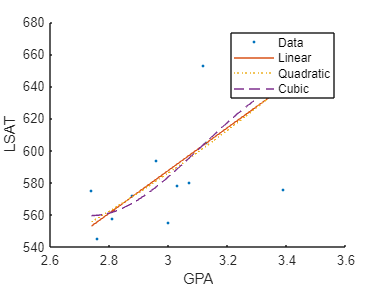

A = ones(15,4);
A(:,2) = gpa;
A(:,3) = gpa .^2;
A(:,4) = gpa .^3;

AT = A';
AS = AT * A;
BS = AT * lsat;

xs= AS\BS;

x = linspace(min(gpa), max(gpa),500);
cub = xs(1) + xs(2)*x + xs(3)*x.^2 + xs(4)*x.^3;
plot(x, cub,"--")
legend("Data", "Linear", "Quadratic", "Cubic")

**Error**

e2 = lsat-(A*xs);
MSE = (norm(e2)^2)/15

MSE = 636.1159